addpath(genpath("C:\Users\agori\Documents\MATLAB\3D-Sea-Ice\FineAlignment\GliraICP"));
ICPoutlier=load("C:\Users\agori\Documents\MATLAB\MSc\Validation\2blocksROS2\AfterOutlierRemoved\ICP.mat");
ICPraw=load("C:\Users\agori\Documents\MATLAB\MSc\Validation\2blocksROS2\AfterNew\ICP.mat");

pcTest=pointCloud('Btest.ply');

2025-03-18 12:54:39.849s | S : POINTCLOUD > IMPORT
                 +0.003s | I : POINTCLOUD > IMPORT : Point cloud label = 'Btest.ply'
2025-03-18 12:54:39.855s | S : POINTCLOUD > IMPORT > READ DATA
                 +0.057s | E : POINTCLOUD > IMPORT > READ DATA
                 +0.071s | E : POINTCLOUD > IMPORT
2025-03-18 12:54:39.922s | S : POINTCLOUD > INFO
                 +0.001s | I : POINTCLOUD > INFO : Point cloud label = 'Btest.ply'
                         | V :       9890           = number of             points
                         | V :       9890           = number of   activated points
                         | V :          0           = number of deactivated points
                         | V :         -0.315       = min / x
                         | V :          1.325       = max / x
                         | V :         -0.542       = min / y
                         | V :          0.790       = max / y
                         | V :          0.064       = min 

2025-03-18 12:54:44.826s | S : POINTCLOUD > SELECT > ALL
                 +0.003s | I : POINTCLOUD > SELECT > ALL : Point cloud label = 'Btest.ply'
                         | V :       9890           = number of activated points before filtering
                         | V :       9890           = number of activated points after filtering
                 +0.010s | E : POINTCLOUD > SELECT > ALL


pcTest.select('All');
tic
%pcTest.normals(0.1,'MaxNoNeighbours',6);
pcTest.normals(0.1);

2025-03-18 12:55:46.260s | S : POINTCLOUD > NORMALS
                 +0.003s | I : POINTCLOUD > NORMALS : Point cloud label = 'Btest.ply'
2025-03-18 12:55:46.267s | S : POINTCLOUD > NORMALS > NNSEARCH
                 +0.054s | E : POINTCLOUD > NORMALS > NNSEARCH
2025-03-18 12:55:46.323s | S : POINTCLOUD > NORMALS > PCA
                         | V :       9890           = no. of activated points
                         | V :       9881           = normal computation   successful
                         | V :          9           = normal computation unsuccessful
                 +0.412s | E : POINTCLOUD > NORMALS > PCA
                 +0.477s | E : POINTCLOUD > NORMALS


toc

Elapsed time is 0.484723 seconds.


2025-03-18 13:01:56.710s | S : POINTCLOUD > COPY
                 +0.003s | I : POINTCLOUD > COPY : Point cloud label = 'Btest.ply'
                 +0.009s | E : POINTCLOUD > COPY


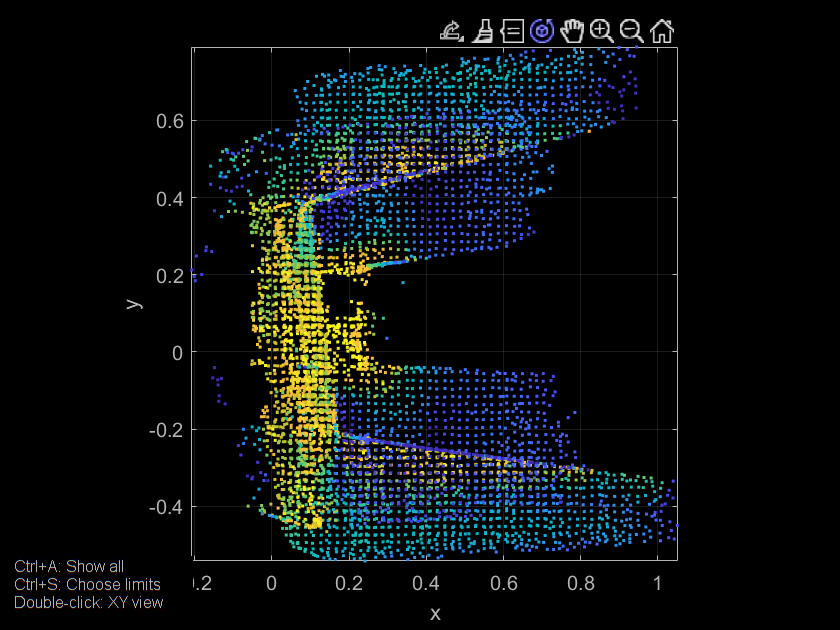

pcTest.plot('Color', 'A.roughness', 'MarkerSize', 5);

 pcTest.select('Attribute', 'roughness', [0 0.03]);

2025-03-18 13:01:48.249s | S : POINTCLOUD > SELECT > ATTRIBUTE
                 +0.003s | I : POINTCLOUD > SELECT > ATTRIBUTE : Point cloud label = 'Btest.ply'
                         | V :       8172           = number of activated points before filtering
                         | V :       8172           = number of activated points after filtering
                 +0.011s | E : POINTCLOUD > SELECT > ATTRIBUTE


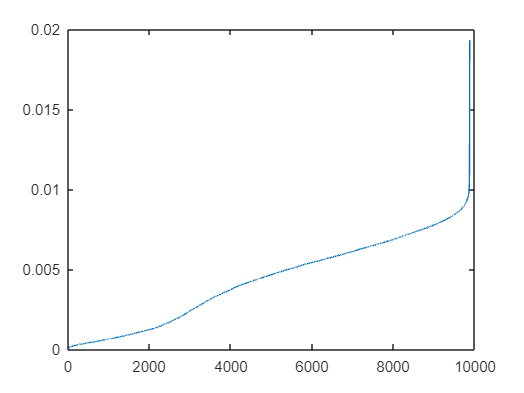

plot(sort(pcTest.A.roughness))

pcTest.select('NormalSampling', 25);

2025-03-18 12:52:35.862s | S : POINTCLOUD > SELECT > NORMALSAMPLING
                 +0.003s | I : POINTCLOUD > SELECT > NORMALSAMPLING : Point cloud label = 'Btest.ply'
                         | V :       9890           = number of activated points before filtering
2025-03-18 12:52:35.905s | S : POINTCLOUD > ADDATTRIBUTE
                 +0.002s | I : POINTCLOUD > ADDATTRIBUTE : Point cloud label = 'Btest.ply'
                 +0.061s | E : POINTCLOUD > ADDATTRIBUTE
2025-03-18 12:52:35.969s | S : POINTCLOUD > ADDATTRIBUTE
                 +0.002s | I : POINTCLOUD > ADDATTRIBUTE : Point cloud label = 'Btest.ply'
                 +0.007s | E : POINTCLOUD > ADDATTRIBUTE
                         | V :       2472           = number of activated points after filtering
                 +0.345s | E : POINTCLOUD > SELECT > NORMALSAMPLING


 pcTest.select('Attribute', 'roughness', [0 0.02]);

2025-03-18 12:49:58.040s | S : POINTCLOUD > SELECT > ATTRIBUTE
                 +0.004s | I : POINTCLOUD > SELECT > ATTRIBUTE : Point cloud label = 'Btest.ply'
                         | V :       9890           = number of activated points before filtering
                         | V :       9881           = number of activated points after filtering
                 +0.013s | E : POINTCLOUD > SELECT > ATTRIBUTE


pcTest.select('All')

2025-03-18 12:58:41.226s | S : POINTCLOUD > SELECT > ALL
                 +0.003s | I : POINTCLOUD > SELECT > ALL : Point cloud label = 'Btest.ply'
                         | V :       6257           = number of activated points before filtering
                         | V :       9890           = number of activated points after filtering
                 +0.010s | E : POINTCLOUD > SELECT > ALL


2025-03-18 12:52:42.702s | S : POINTCLOUD > COPY
                 +0.004s | I : POINTCLOUD > COPY : Point cloud label = 'Btest.ply'
                 +0.010s | E : POINTCLOUD > COPY


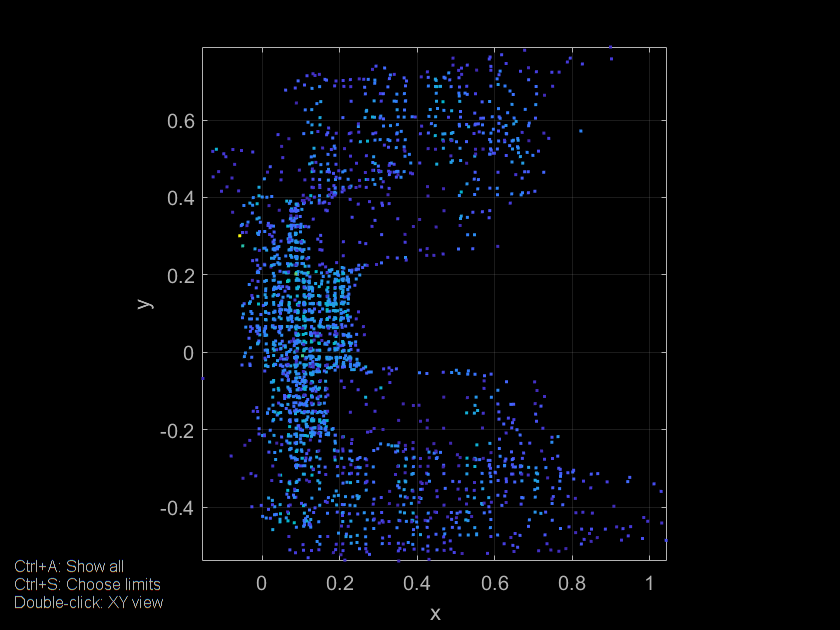

 pcTest.plot('Color', 'A.roughness', 'MarkerSize', 5);

pcTest = pointCloud('C:\Users\agori\Documents\MATLAB\MSc\Validation\2blocksROS2\BeforeAlignment\2blocksB.ply');

2025-03-18 12:20:49.756s | S : POINTCLOUD > IMPORT
                 +0.016s | I : POINTCLOUD > IMPORT : Point cloud label = '2blocksB.ply'
2025-03-18 12:20:49.796s | S : POINTCLOUD > IMPORT > READ DATA
                 +0.671s | E : POINTCLOUD > IMPORT > READ DATA
                 +0.714s | E : POINTCLOUD > IMPORT
2025-03-18 12:20:50.491s | S : POINTCLOUD > INFO
                 +0.005s | I : POINTCLOUD > INFO : Point cloud label = '2blocksB.ply'
                         | V :      45715           = number of             points
                         | V :      45715           = number of   activated points
                         | V :          0           = number of deactivated points
                         | V :         -0.322       = min / x
                         | V :          1.325       = max / x
                         | V :         -0.544       = min / y
                         | V :          0.790       = max / y
                         | V :          0.064       

pcTest.select('All');

2025-03-18 12:20:54.423s | S : POINTCLOUD > SELECT > ALL
                 +0.012s | I : POINTCLOUD > SELECT > ALL : Point cloud label = '2blocksB.ply'
                         | V :      45715           = number of activated points before filtering
                         | V :      45715           = number of activated points after filtering
                 +0.056s | E : POINTCLOUD > SELECT > ALL


pcTest.normals(1,'MaxNoNeighbours',6);

2025-03-18 12:21:03.446s | S : POINTCLOUD > NORMALS
                 +0.026s | I : POINTCLOUD > NORMALS : Point cloud label = '2blocksB.ply'
2025-03-18 12:21:03.502s | S : POINTCLOUD > NORMALS > NNSEARCH


pcTest.plot('Color', 'r', 'MarkerSize', 5);

2025-03-18 12:05:03.497s | S : POINTCLOUD > COPY
                 +0.005s | I : POINTCLOUD > COPY : Point cloud label = '2blocksB.ply'
                 +0.032s | E : POINTCLOUD > COPY


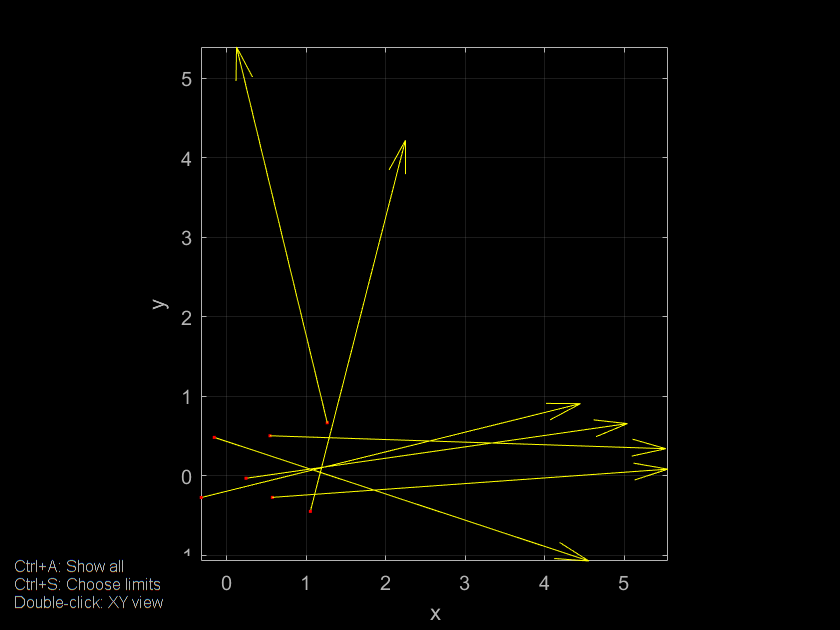

pcTest.plotNormals('Color', 'y', 'Scale', 5);

pcTest.select('All', 1);

2025-03-18 11:52:17.133s | S : POINTCLOUD > SELECT > ALL
                 +0.006s | I : POINTCLOUD > SELECT > ALL : Point cloud label = '2blocksB.ply'
                         | V :      45715           = number of activated points before filtering
                         | V :      45715           = number of activated points after filtering
                 +0.016s | E : POINTCLOUD > SELECT > ALL


pcTest.normals(1);
%   pc.plot('Color', 'r', 'MarkerSize', 5);
%   pc.plotNormals('Color', 'y', 'Scale', 5);

ICPoutlier_stats=ICPoutlier.obj.D.stats;
ICPraw_stats=ICPraw.obj.D.stats;

arrMean_outlier=zeros(1, 5); 
arrMean_raw=zeros(1, 5); 
arrStd_outlier=zeros(1, 5); 
arrStd_raw=zeros(1, 5); 
arrNobs_outlier=zeros(1, 5); 
arrNobs_raw=zeros(1, 5); 
arrNorms_outlier=zeros(1, 5); 
arrNorms_raw=zeros(1, 5); 
%ICPoutlier_stats{1,1}.mean_vWithoutGrossErrors;
for k=1:5
    arrMean_outlier(k)=ICPoutlier_stats{1,k}.mean_vWithoutGrossErrors;
    arrMean_raw(k)=ICPraw_stats{1,k}.mean_vWithoutGrossErrors;
    
    arrStd_outlier(k)= ICPoutlier_stats{1,k}.std_vWithoutGrossErrors;
    arrStd_raw(k)=ICPraw_stats{1,k}.std_vWithoutGrossErrors;

    arrNobs_outlier(k)=ICPoutlier_stats{1,k}.nObs;
    arrNobs_raw(k)=ICPraw_stats{1,k}.nObs; 

    arrNorms_outlier(k)= ICPoutlier_stats{1,k}.normdx;
    arrNorms_raw(k)=ICPraw_stats{1,k}.normdx;
end

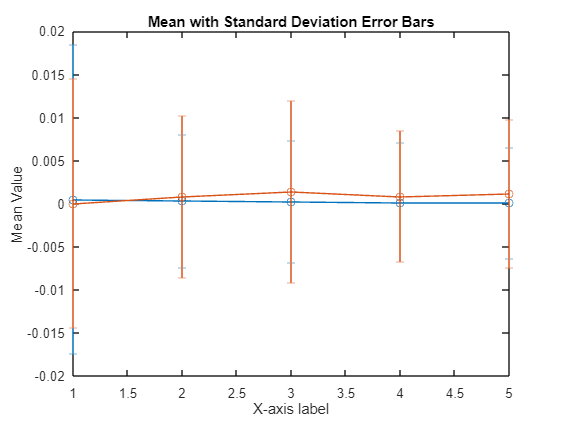

nums=1:5;
errorbar(nums, arrMean_raw, arrStd_raw, 'o-');
hold on
errorbar(nums, arrMean_outlier, arrStd_outlier, 'o-');
hold off
xlabel('X-axis label');
ylabel('Mean Value');
title('Mean with Standard Deviation Error Bars');

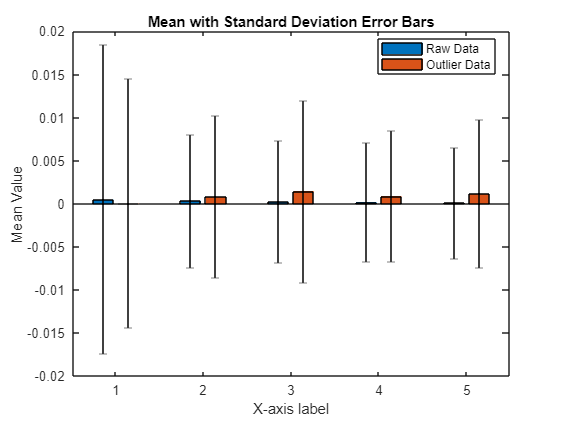

nums = 1:5; % X-axis categories


% Combine means into a matrix (each row corresponds to a category)
means = [arrMean_raw; arrMean_outlier]';

% Create grouped bar plot
figure;
b = bar(nums, means, 'grouped');
hold on;

% Calculate bar centers for error bars
numGroups = size(means, 1); % Number of x-axis points
numBars = size(means, 2);   % Number of bars per group
groupWidth = min(0.8, numBars / (numBars + 1.5)); % Width of bar groups

for i = 1:numBars
    xOffsets = b(i).XEndPoints; % X positions for each bar
    if i == 1
        errorbar(xOffsets, arrMean_raw, arrStd_raw, 'k', 'linestyle', 'none');
    else
        errorbar(xOffsets, arrMean_outlier, arrStd_outlier, 'k', 'linestyle', 'none');
    end
end

hold off;
xlabel('X-axis label');
ylabel('Mean Value');
title('Mean with Standard Deviation Error Bars');
legend({'Raw Data', 'Outlier Data'}, 'Location', 'Best');

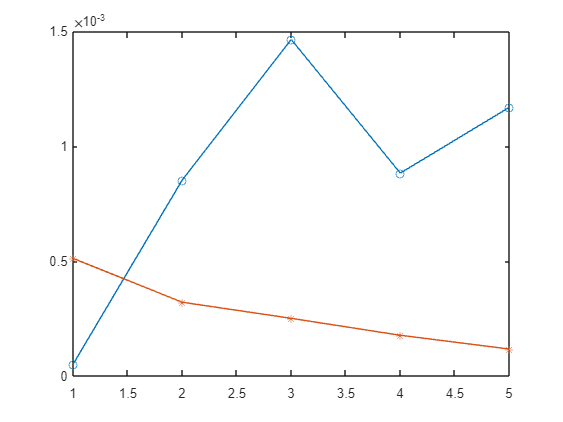

plot(nums,arrMean_outlier,'o-');
hold on
plot(nums,arrMean_raw,'*-');
hold off

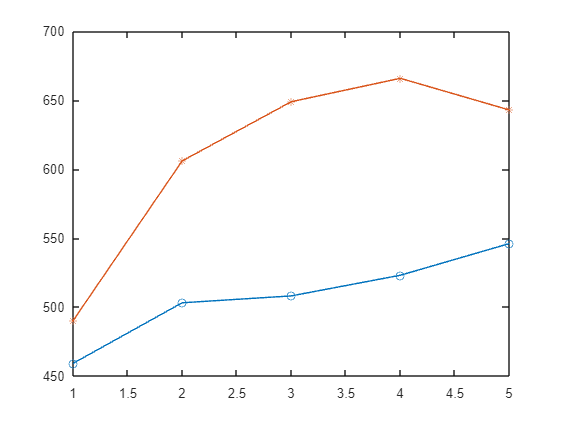

plot(nums,arrNobs_outlier,'o-');
hold on
plot(nums,arrNobs_raw,'*-');
hold off

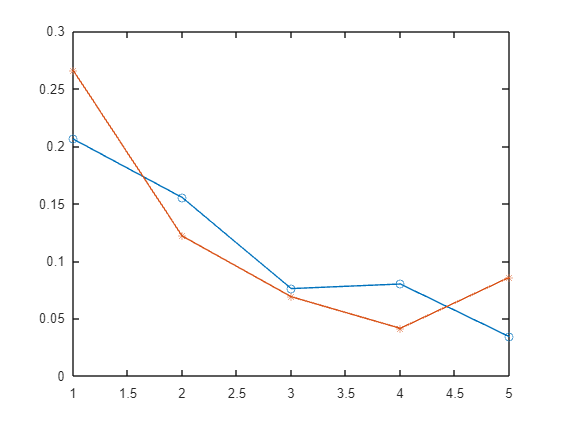

plot(nums,arrNorms_outlier,'o-');
hold on
plot(nums,arrNorms_raw,'*-');
hold off

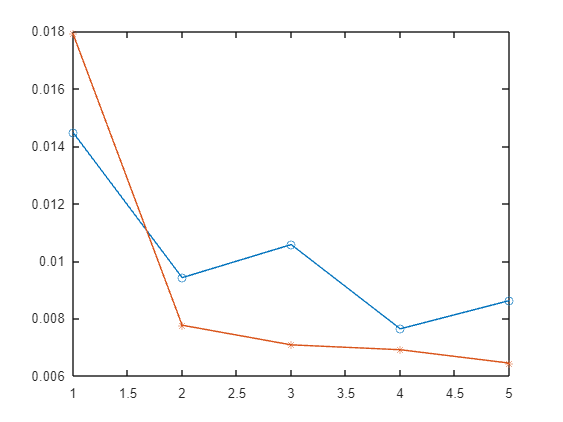

plot(nums,arrStd_outlier,'o-');
hold on
plot(nums,arrStd_raw,'*-');
hold off

Comparison of tforms

tformB_outlier=ICPoutlier.obj.D.H{1, 2};
tformB_raw=ICPraw.obj.D.H{1, 2};
[rotDiff, transDiff] = tformCompare(tformB_outlier,tformB_raw);

Rotation Difference: 1.825298 degrees
Translation Difference: 0.036913 units


rotDiff = 1.8253

transDiff = 0.0369

arrTformDiff_trans=zeros(1,8);
arrTformDiff_rot=zeros(1,8);
for k=1:8
    disp(k);
    tform1=ICPoutlier.obj.D.H{1, k};
    tform2=ICPraw.obj.D.H{1, k};
    [arrTformDiff_rot(k),arrTformDiff_trans(k)]=tformCompare(tform1,tform2);
end

     1



Rotation Difference: 0.000000 degrees
Translation Difference: 0.000000 units
T1
Rotation axis:
     0     0     1

Rotation angle (in degrees):
     0

Translation vector:
     0
     0
     0

T2
Rotation axis:
     0     0     1

Rotation angle (in degrees):
     0

Translation vector:
     0
     0
     0

------------------------


     2



Rotation Difference: 1.825298 degrees
Translation Difference: 0.036913 units
T1
Rotation axis:
   -0.1361   -0.0716   -0.9881

Rotation angle (in degrees):
    1.0783

Translation vector:
    0.0220
   -0.1083
    0.0088

T2
Rotation axis:
    0.0700    0.1349   -0.9884

Rotation angle (in degrees):
    4.6697

Translation vector:
    0.0207
   -0.0728
   -0.0012

------------------------


     3



Rotation Difference: 1.034722 degrees
Translation Difference: 0.047919 units
T1
Rotation axis:
    0.1212    0.4828    0.8673

Rotation angle (in degrees):
    1.5874

Translation vector:
   -0.0882
   -0.1615
    0.0115

T2
Rotation axis:
    0.9016   -0.4322   -0.0163

Rotation angle (in degrees):
    1.1597

Translation vector:
   -0.0768
   -0.1169
    0.0250

------------------------


     4



Rotation Difference: 0.918495 degrees
Translation Difference: 0.068931 units
T1
Rotation axis:
    0.2453    0.3574    0.9012

Rotation angle (in degrees):
    1.0914

Translation vector:
    0.0139
   -0.0571
    0.0231

T2
Rotation axis:
    0.9073   -0.4204    0.0030

Rotation angle (in degrees):
    1.5618

Translation vector:
    0.0310
    0.0090
    0.0327

------------------------


     5



Rotation Difference: 3.210153 degrees
Translation Difference: 0.131154 units
T1
Rotation axis:
    0.1338   -0.0314   -0.9905

Rotation angle (in degrees):
    2.6130

Translation vector:
   -0.0420
    0.0499
   -0.0123

T2
Rotation axis:
    0.1063   -0.0771   -0.9913

Rotation angle (in degrees):
    9.0280

Translation vector:
   -0.0174
    0.1693
    0.0361

------------------------


     6



Rotation Difference: 0.643884 degrees
Translation Difference: 0.051516 units
T1
Rotation axis:
   -0.0135    0.0144   -0.9998

Rotation angle (in degrees):
    4.2462

Translation vector:
    0.0565
   -0.0379
    0.0038

T2
Rotation axis:
    0.2010   -0.1558   -0.9671

Rotation angle (in degrees):
    4.6457

Translation vector:
    0.0788
   -0.0124
    0.0425

------------------------


     7



Rotation Difference: 0.611347 degrees
Translation Difference: 0.049076 units
T1
Rotation axis:
   -0.1322   -0.1980   -0.9712

Rotation angle (in degrees):
    3.2140

Translation vector:
    0.0596
   -0.0381
   -0.0062

T2
Rotation axis:
    0.2001   -0.2843   -0.9376

Rotation angle (in degrees):
    3.5729

Translation vector:
    0.0685
   -0.0118
    0.0343

------------------------


     8



Rotation Difference: 5.530430 degrees
Translation Difference: 0.037078 units
T1
Rotation axis:
   -0.0852    0.0282   -0.9960

Rotation angle (in degrees):
    6.5062

Translation vector:
    0.1212
   -0.0266
    0.0074

T2
Rotation axis:
    0.0063   -0.3050    0.9523

Rotation angle (in degrees):
    4.6705

Translation vector:
    0.1138
   -0.0615
   -0.0027

------------------------


corrPointsBraw=ICPraw.obj.CP.PostICP{1, 1}.X2;
pcTest = pointCloud('C:\Users\agori\Documents\MATLAB\MSc\Validation\2blocksROS2\AfterNew\2blocksB_POSTICP.mat');

2025-03-17 11:41:52.216s | S : POINTCLOUD > IMPORT
2025-03-17 11:41:52.237s | S : POINTCLOUD > IMPORT > LOAD FROM MAT FILE
                 +0.033s | E : POINTCLOUD > IMPORT > LOAD FROM MAT FILE
                 +0.053s | E : POINTCLOUD > IMPORT


%   % Note: the imported attributes are saved as fields in the structure pc.A,
%   % e.g. the roughness is saved in pc.A.roughness.
%pcTest.plot('Color', 'A.roughness');
pcTest.plot;

2025-03-17 11:41:53.144s | S : POINTCLOUD > COPY
                 +0.009s | I : POINTCLOUD > COPY : Point cloud label = '2blocksB.ply'
                 +0.036s | E : POINTCLOUD > COPY


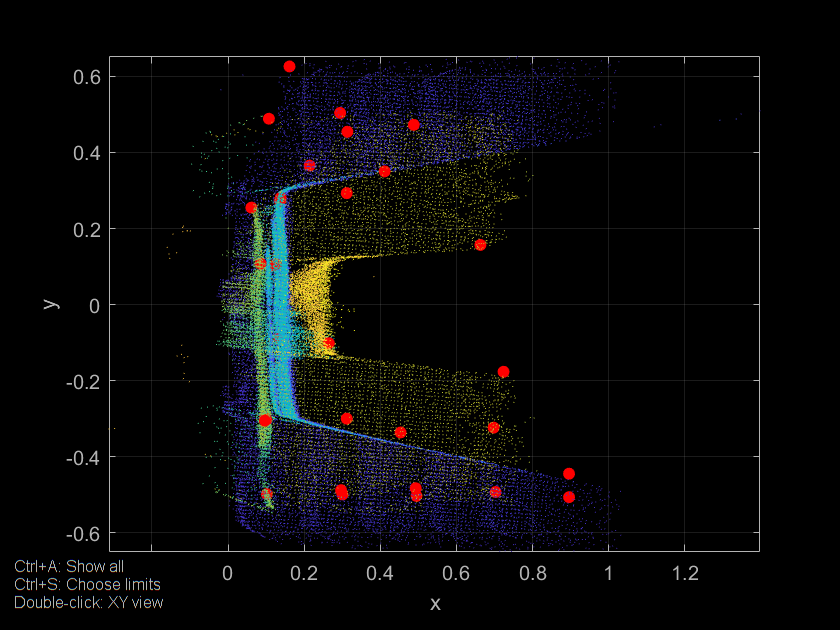

hold on
scatter3(corrPointsBraw(:,1), corrPointsBraw(:,2), corrPointsBraw(:,3), 'r', 'filled');
hold off;

corrPointsBoutlier=ICPoutlier.obj.CP.PostICP{1, 1}.X2;
pcTestOutlier = pointCloud('C:\Users\agori\Documents\MATLAB\MSc\Validation\2blocksROS2\AfterOutlierRemoved\blocksB_POSTICP.mat');

2025-03-17 12:15:01.199s | S : POINTCLOUD > IMPORT
2025-03-17 12:15:01.216s | S : POINTCLOUD > IMPORT > LOAD FROM MAT FILE
                 +0.065s | E : POINTCLOUD > IMPORT > LOAD FROM MAT FILE
                 +0.098s | E : POINTCLOUD > IMPORT


%   % Note: the imported attributes are saved as fields in the structure pc.A,
%   % e.g. the roughness is saved in pc.A.roughness.
%pcTest.plot('Color', 'A.roughness');
pcTestOutlier.plot;

2025-03-17 12:15:02.353s | S : POINTCLOUD > COPY
                 +0.006s | I : POINTCLOUD > COPY : Point cloud label = 'blocksB.ply'
                 +0.023s | E : POINTCLOUD > COPY


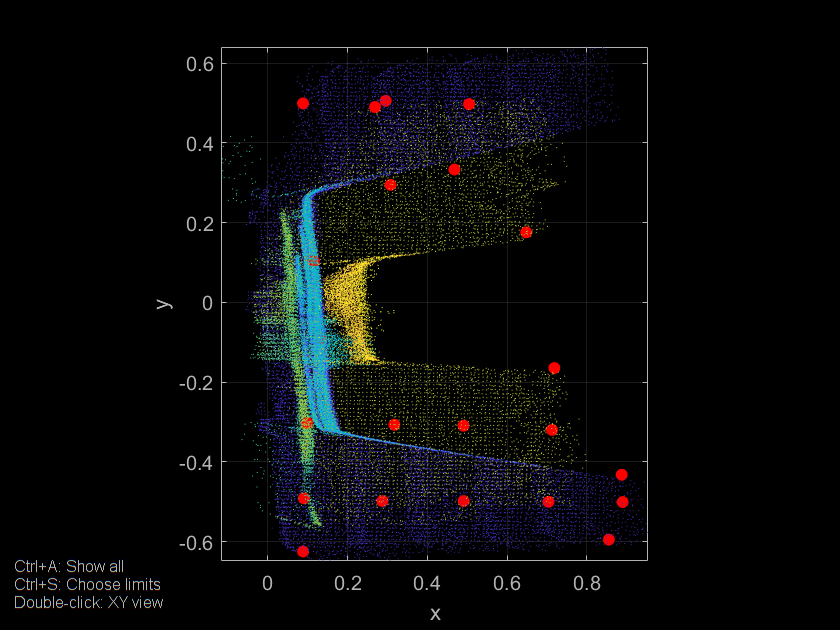

hold on
scatter3(corrPointsBoutlier(:,1), corrPointsBoutlier(:,2), corrPointsBoutlier(:,3), 'r', 'filled');
hold off;